# Practica 2                        Fecha de entrega: 20/sep/2023

**# Lista:** 1          **Alumno:** Valeria Jahzeel Castañon Hernandez        **Tipo de practica:** Individual

**Objetivo:** Que el alumno realize graficos y programas sencillos usando matlab

**Material y equipo:** Computadora con matlab 

----------------------------------------------------------------------------------------------------------------------------------  

Variables utilizadas para todas las funciones

t = -15:15;
adelanto = t+3;
retraso = t-5;
reflexion = -t;
compresion = 2*t;
dilatacion = t/2;

## Funcion escalon unidad: u(t)

u = zeros(1, length(t));  % u es del mismo tamaño que t

for i = 1:length(t)  
    if t(i) < 0  
        u(i) = 0;  
    end
    if t(i) > 0
        u(i) = 1;
    end
end

Se desplaza en el tiempo a la derecha y a la izquierda, se muestra junto con la funcion original para comparar los cambios

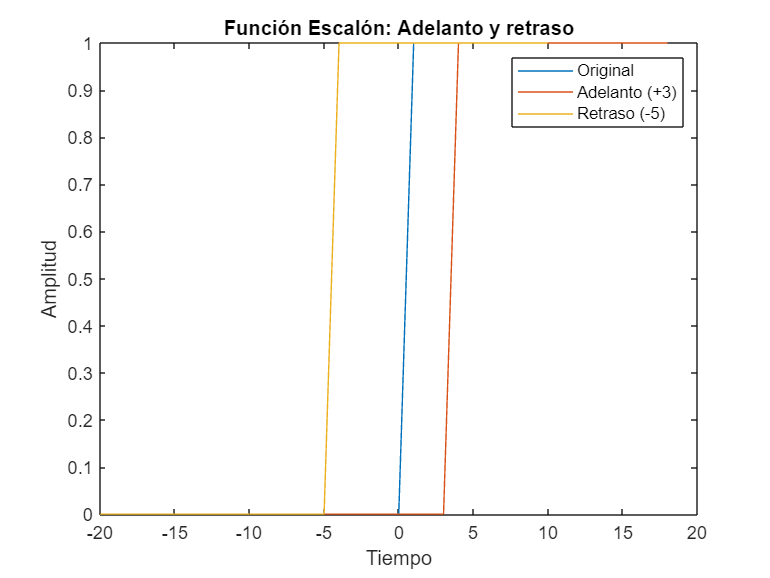

plot(t, u, adelanto, u, retraso, u);
legend('Original','Adelanto (+3)','Retraso (-5)');
title('Función Escalón: Adelanto y retraso');
xlabel('Tiempo');
ylabel('Amplitud');

Reflexion de la funcion escalon

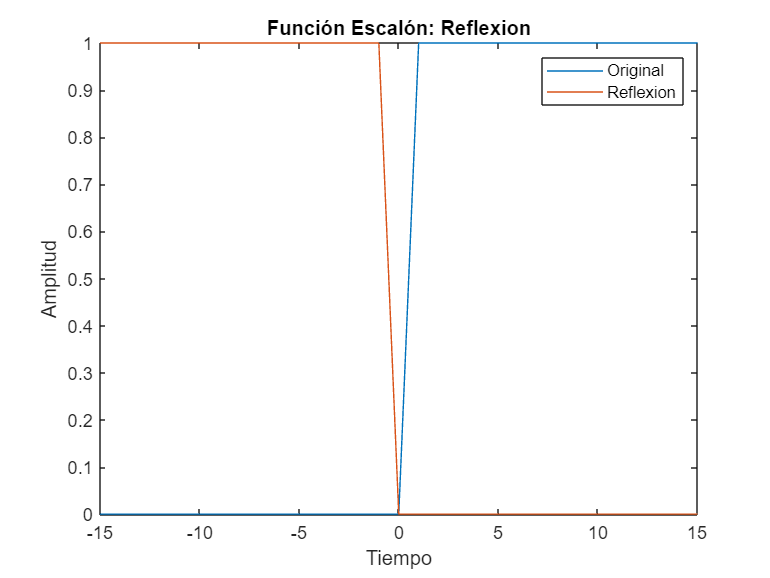

plot(t, u, reflexion, u);
legend('Original', 'Reflexion');
title('Función Escalón: Reflexion');
xlabel('Tiempo');
ylabel('Amplitud');

Compresion y dilatacion de la grafica de la función escalón

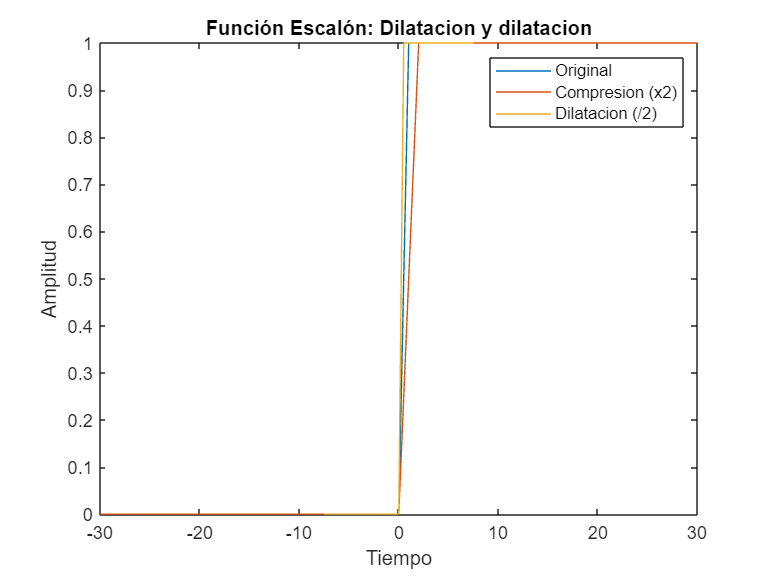

plot(t, u, compresion, u, dilatacion, u);
legend('Original','Compresion (x2)','Dilatacion (/2)');
title('Función Escalón: Dilatacion y dilatacion');
xlabel('Tiempo');
ylabel('Amplitud');

## Funcion delta de Dirac: s(t)

s = zeros(1, length(t));  % u es del mismo tamaño que t

for i = 1:length(t)
    if t(i) == 0
        s(i) = 1;
    else
        s(i) = 0;
    end
end

Desplazamos la grafica a la derecha y a la izquierda

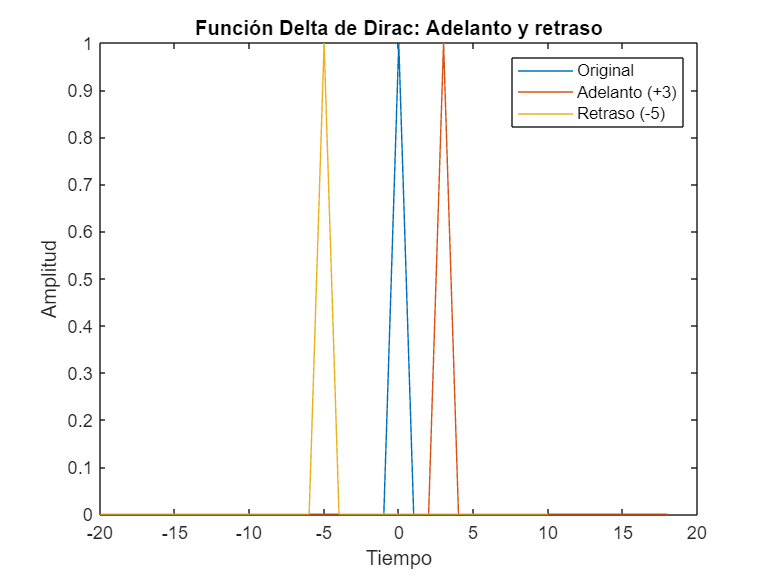

plot(t, s, adelanto , s, retraso, s);
legend('Original','Adelanto (+3)','Retraso (-5)');

title('Función Delta de Dirac: Adelanto y retraso');
xlabel('Tiempo');
ylabel('Amplitud');

Reflexion de la funcion delta de dirac

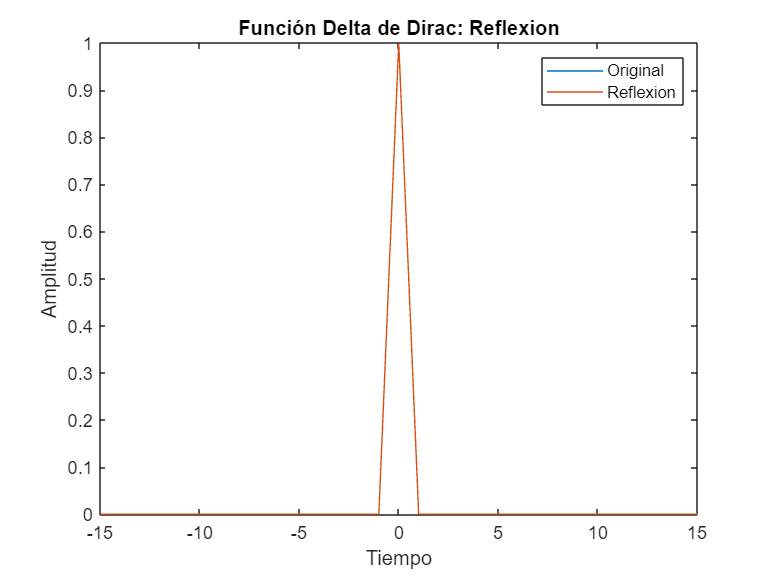

plot(t, s, reflexion, s);
legend('Original', 'Reflexion');

title('Función Delta de Dirac: Reflexion');
xlabel('Tiempo');
ylabel('Amplitud');

Compresión y dilatación de la grafica de la función delta de Dirac

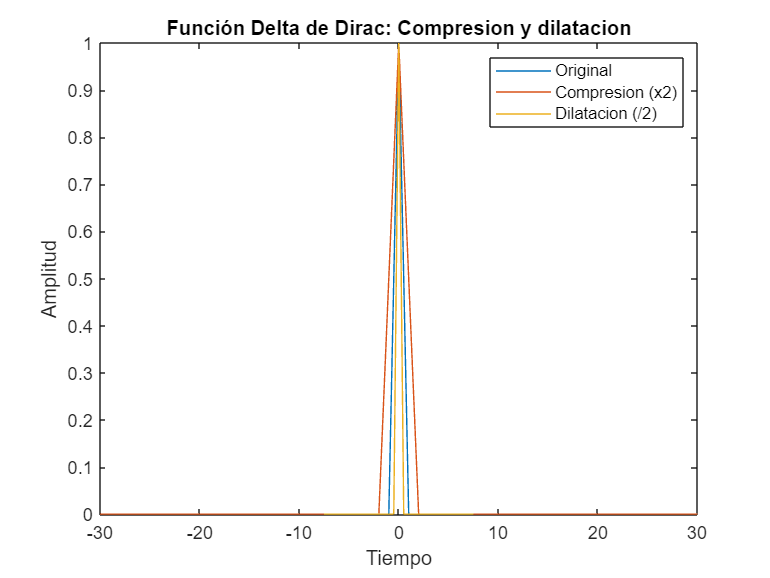

plot(t, s, compresion , s, dilatacion, s);
legend('Original','Compresion (x2)','Dilatacion (/2)');

title('Función Delta de Dirac: Compresion y dilatacion');
xlabel('Tiempo');
ylabel('Amplitud');

## Funcion rampa unidad: r(t)

r = zeros(1, length(t));  % u es del mismo tamaño que t

for i = 1:length(t)
    if t(i) > 0
       r(i) = t(i)*u(i);
    end
    if t(i) <= 0
      r(i) = 0;
    end
end

Se adelanta y se retraza la grafica

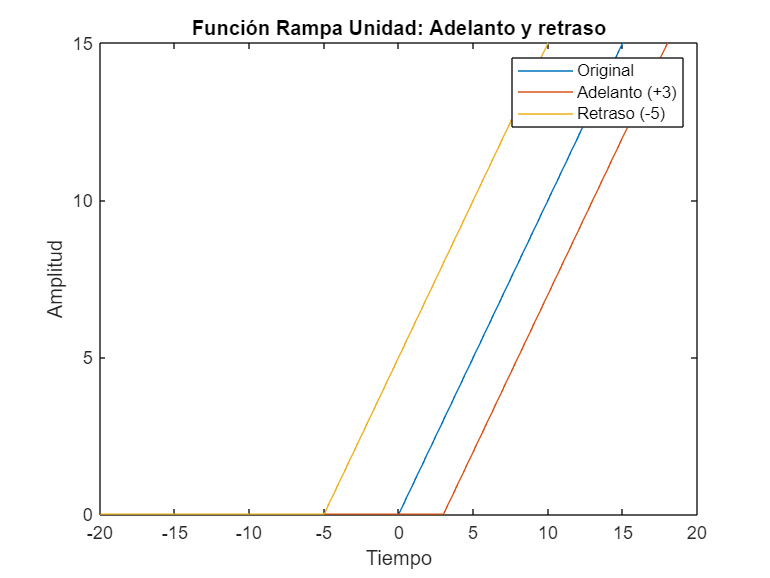

plot(t, r, adelanto, r, retraso, r);
legend('Original','Adelanto (+3)','Retraso (-5)');

title('Función Rampa Unidad: Adelanto y retraso');
xlabel('Tiempo');
ylabel('Amplitud');

Reflecion de la funcion rampa

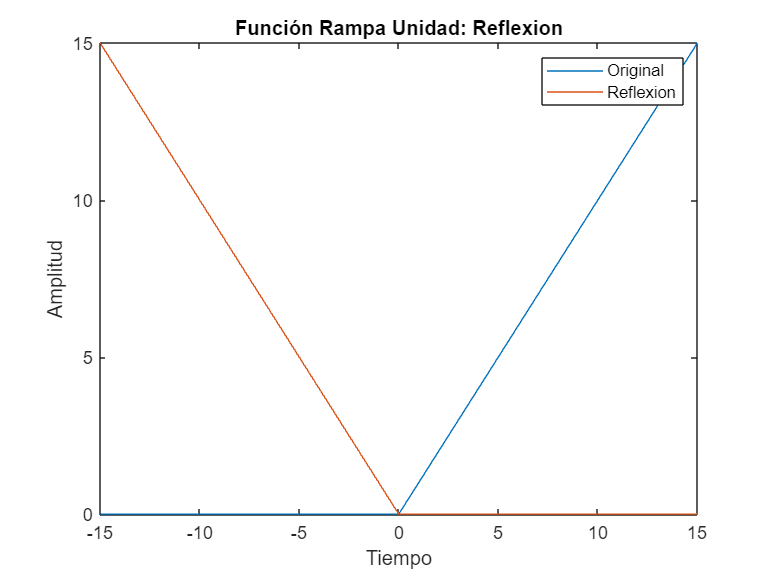

plot(t, r, reflexion, r);
legend('Original','Reflexion');

title('Función Rampa Unidad: Reflexion');
xlabel('Tiempo');
ylabel('Amplitud');

Compresión y dilatación de la grafica de la función rampa

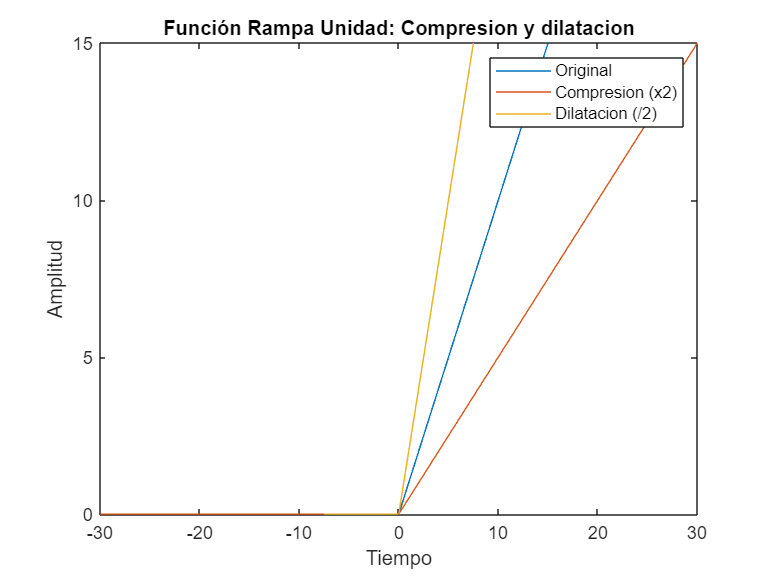

plot(t, r, compresion , r, dilatacion, r);
legend('Original','Compresion (x2)','Dilatacion (/2)');

title('Función Rampa Unidad: Compresion y dilatacion');
xlabel('Tiempo');
ylabel('Amplitud');

## Funcion pulso unidad: n(t)

n = zeros(1, length(t));  % u es del mismo tamaño que t

for i = 1:length(t)
    if t(i) > -1/2 && t(i) < 1/2
       % Calcula los índices en u usando t(i) y el desplazamiento
       index1 = find(t >= t(i) - 1/2, 1);
       index2 = find(t <= t(i) + 1/2, 1, 'last');
       n(i) = u(index2) - u(index1);
    else
      n(i) = 0;
    end
end

Se muestra la grafica del adelanyo y retraso de la funcion

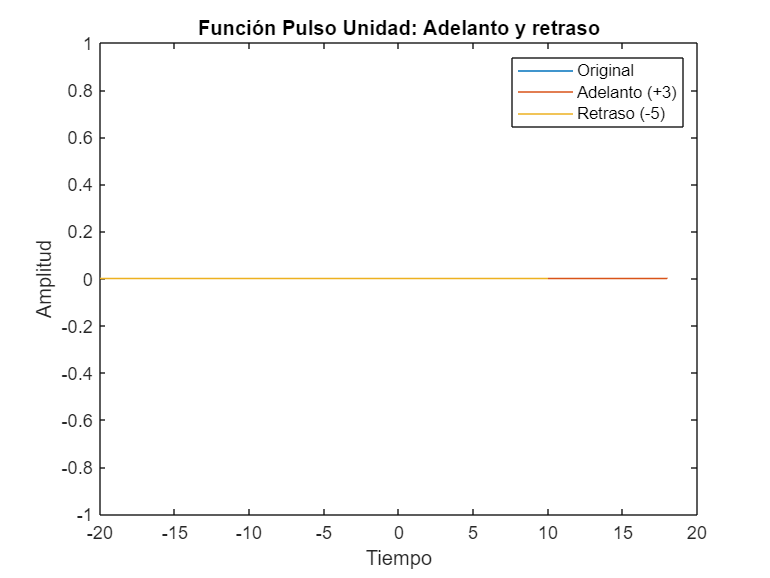

plot(t, n, adelanto, n, retraso, n);
legend('Original','Adelanto (+3)','Retraso (-5)');

title('Función Pulso Unidad: Adelanto y retraso');
xlabel('Tiempo');
ylabel('Amplitud');

Compresión y dilatación de la grafica de la función pulso unidad

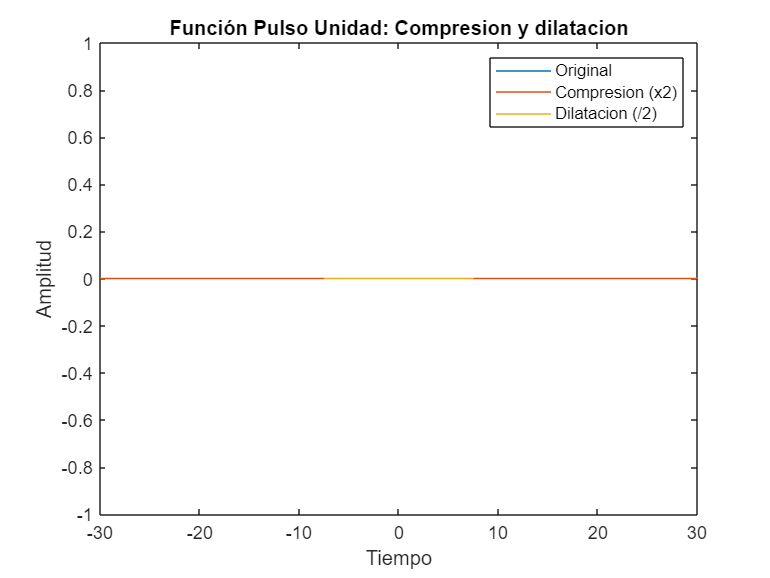

plot(t, n, compresion , n, dilatacion, n);
legend('Original','Compresion (x2)','Dilatacion (/2)');

title('Función Pulso Unidad: Compresion y dilatacion');
xlabel('Tiempo');
ylabel('Amplitud');

Reflexion de la funcion pulso

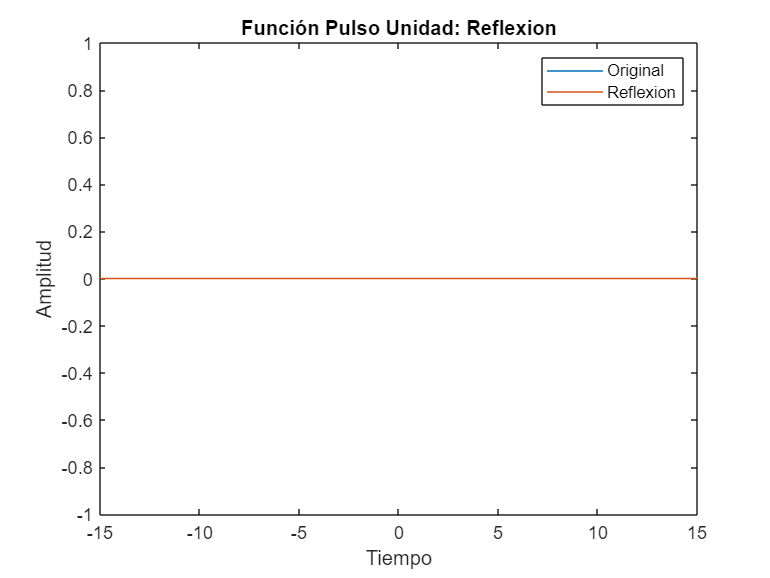

plot(t, n, reflexion, n);
legend('Original','Reflexion');

title('Función Pulso Unidad: Reflexion');
xlabel('Tiempo');
ylabel('Amplitud');

## Funcion triangular de unidad: tri(t)

tri = zeros(1, length(t));  % u es del mismo tamaño que t

for i = 1:length(t)
    if t(i) > -1 && t(i) < 1
       % Calcula los índices en r usando t(i) y el desplazamiento
       index1 = find(t >= t(i) - 1, 1);
       index2 = find(t <= t(i) - 1, 1, 'last');
       index3 = find(t >= t(i), 1);
       index4 = find(t <= t(i), 1, 'last');
       index5 = find(t >= t(i) + 1, 1);
       index6 = find(t <= t(i) + 1, 1, 'last');
       
       tri(i) = r(index3) - 2 * r(index4) + r(index5);
    else
       tri(i) = 0;
    end
end     

Se imprime el grafico con el adelanto y el retraso de la funcion 

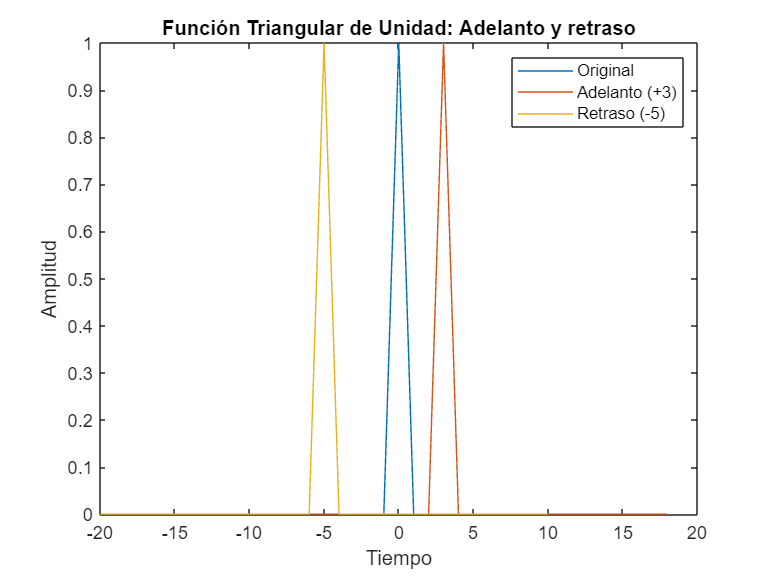

plot(t, tri, adelanto, tri, retraso, tri);
legend('Original','Adelanto (+3)','Retraso (-5)');

title('Función Triangular de Unidad: Adelanto y retraso');
xlabel('Tiempo');
ylabel('Amplitud');

Reflexión de la funcion triángular, en este caso no cambia ya que es simétrica

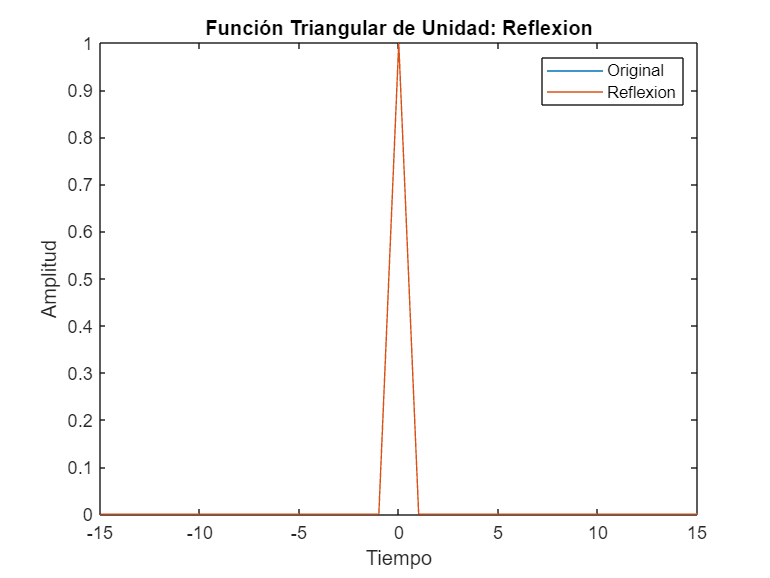

plot(t, tri, reflexion, tri);
legend('Original','Reflexion');

title('Función Triangular de Unidad: Reflexion');
xlabel('Tiempo');
ylabel('Amplitud');

Compresión y dilatación de la grafica de la función delta de Dirac

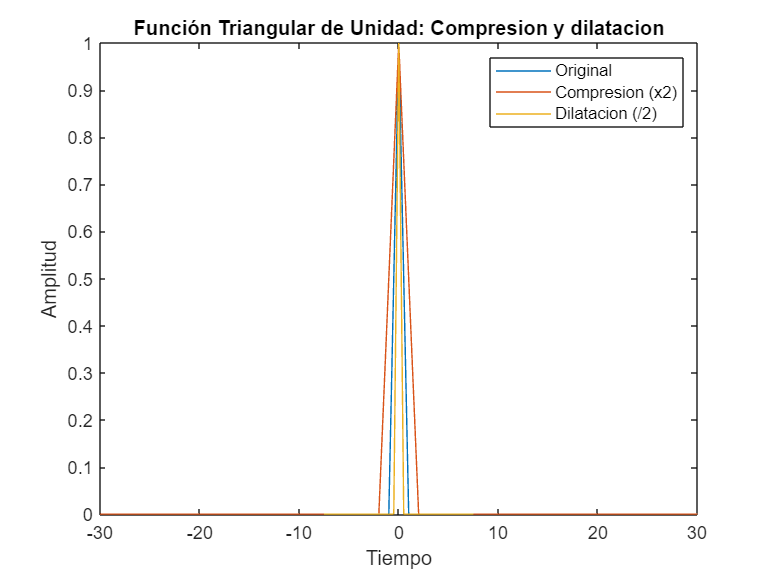

plot(t, tri, compresion , tri, dilatacion, tri);
legend('Original','Compresion (x2)','Dilatacion (/2)');

title('Función Triangular de Unidad: Compresion y dilatacion');
xlabel('Tiempo');
ylabel('Amplitud');

## Funcion Sinc: sinc(t)

t2=linspace(-2*pi,2*pi,100);

sinc=sin(pi*t2)./(t2*pi);

Se muestra el gráfico con el adelanto y el retraso de la funcion

plot(t2, sinc, t2+3, sinc, t2-5, sinc);
legend('Original','Adelanto (+3)','Retraso (-5)');

title('Función Sinc: Adelanto y retraso');
xlabel('Tiempo');
ylabel('Amplitud');

Reflexión de la funcion Sinc, en esta funcion tampoco se observa ningun cambio ya que es simétrica

plot(t2, sinc, -t2, sinc);
legend('Original','Reflexion');

title('Función Sinc: Reflexion');
xlabel('Tiempo');
ylabel('Amplitud');

Compresión y dilatación de la grafica de la función delta de Dirac

plot(t2, sinc, 2*t2 , sinc, t2/2, sinc);
legend('Original','Compresion (x2)','Dilatacion (/2)');

title('Función Sinc: Compresion y dilatacion');
xlabel('Tiempo');
ylabel('Amplitud');

## Representacion de las señales

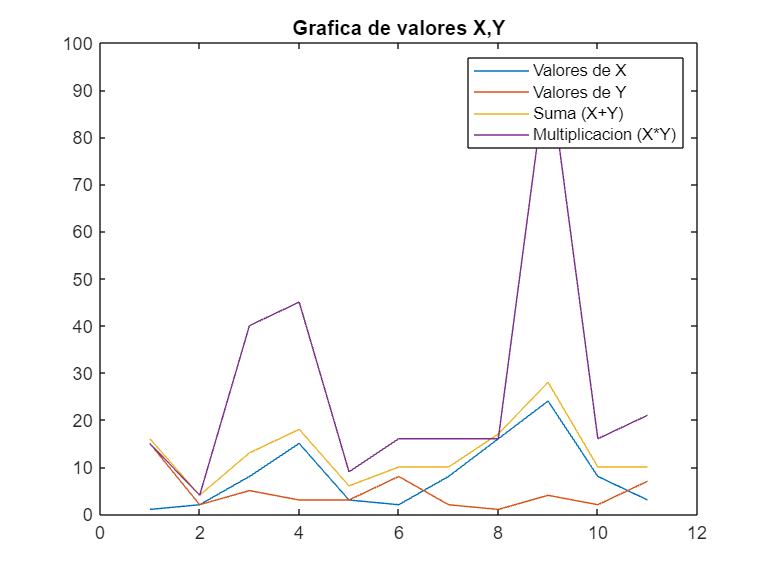

graficaX = 1:11;
x = [1,2,8,15,3,2,8,16,24,8,3];
y = [15,2,5,3,3,8,2,1,4,2,7];

suma = x+y;
multi = x.*y;

plot(graficaX,x, graficaX, y, graficaX, suma, graficaX, multi);
legend('Valores de X','Valores de Y','Suma (X+Y)','Multiplicacion (X*Y)')
title('Grafica de valores X,Y');

### Conclusion

El objetivo de la practica fue cumplido satisfactoriamente, se lograron graficar todas las funciones; sin embargo, la grafica de la funcion Delta de Dirac salió muy parecida a la grafica de la funcion Triangular Unidad, la verdad no se la razón de esto ya que simplemente seguí las fórmulas que se nos proporcionaron en clase. 

Los procesos de adelanto, retraso, reflexión, compresión y dilatación fueron completados exitosamente, sirvió en todos los casos y no hubo ningun problema.

Por ultimo, al hacer la suma y la multiplicación de los ultimos dos vectores, el resultado también fué satisfactorio. La gráfica muestra los resultados obtenidos en cada una de las operaciones realizadas. 